mat=readmatrix('plot.xlsx','Range','A1:C14')

mat = 	1.0e+04 *

    0.0100   -0.0000   -0.0011
    0.0159   -0.0000   -0.0017
    0.0250   -0.0001   -0.0026
    0.0300   -0.0001   -0.0030
    0.0400   -0.0002   -0.0039
    0.1000   -0.0006   -0.0072
    0.1420   -0.0009   -0.0085
    0.1441   -0.0009   -0.0086
    0.1460   -0.0009   -0.0086
    0.1500   -0.0009   -0.0088


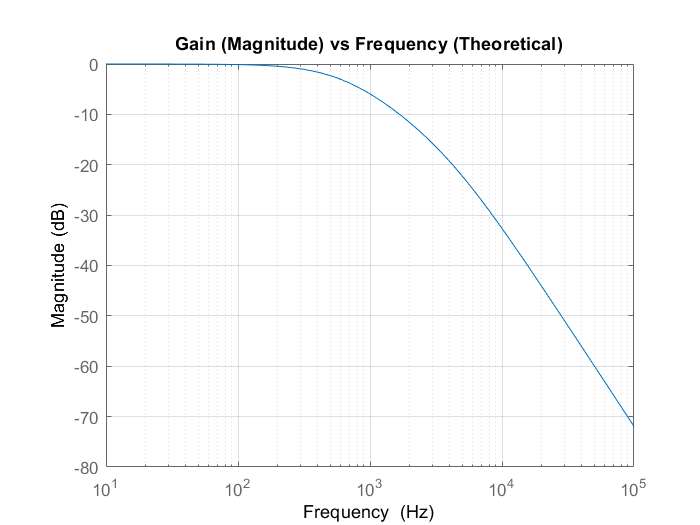

P = bodeoptions('cstprefs');
P.PhaseVisible='off';
P.FreqUnits='Hz';
P.Title.String='Gain (Magnitude) vs Frequency (Theoretical)';
Q = bodeoptions('cstprefs');
Q.MagVisible='off';
Q.FreqUnits='Hz';
Q.Title.String='Gain (Phase) vs Frequency (Theoretical)';
R=3000;
L=0.1;
C=0.1e-6;
sys=tf([1],[L*C, R*C, 1]);
bodeplot(sys,P)
grid on

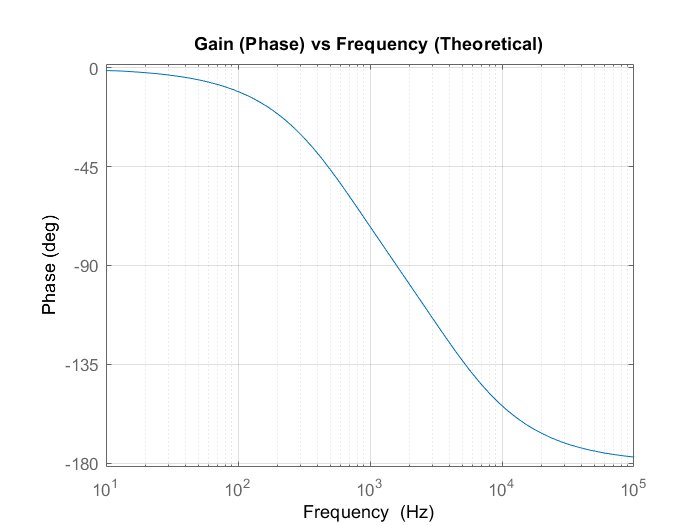

bodeplot(sys,Q)
grid on

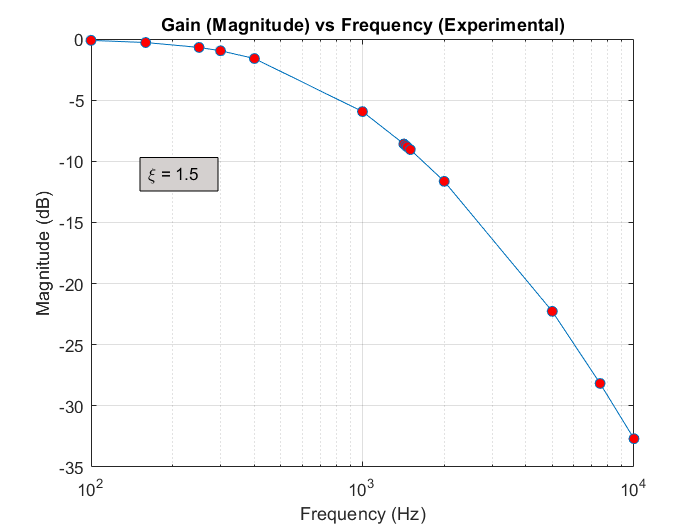

semilogx(mat(:,1),mat(:,2),'-o','MarkerFaceColor','red')
ylabel('Magnitude (dB)')
xlabel('Frequency (Hz)')
title('Gain (Magnitude) vs Frequency (Experimental)')
dim = [.2 .4 .3 .3];
str = '\xi = 1.5';
annotation('textbox',dim,'String',str,'FitBoxToText','on','BackgroundColor','#d4d0cf');
grid on

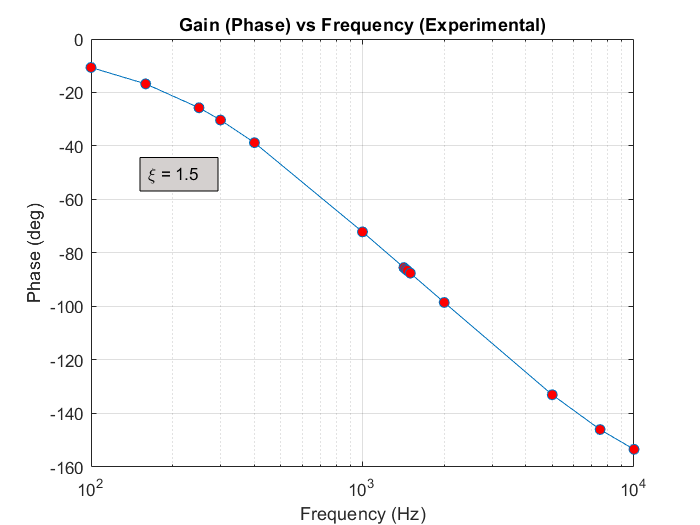

semilogx(mat(:,1),mat(:,3),'-o','MarkerFaceColor','red')
ylabel('Phase (deg)')
xlabel('Frequency (Hz)')
title('Gain (Phase) vs Frequency (Experimental)')
dim = [.2 .4 .3 .3];
str = '\xi = 1.5';
annotation('textbox',dim,'String',str,'FitBoxToText','on','BackgroundColor','#d4d0cf');
grid on